# GFDM System Simulation

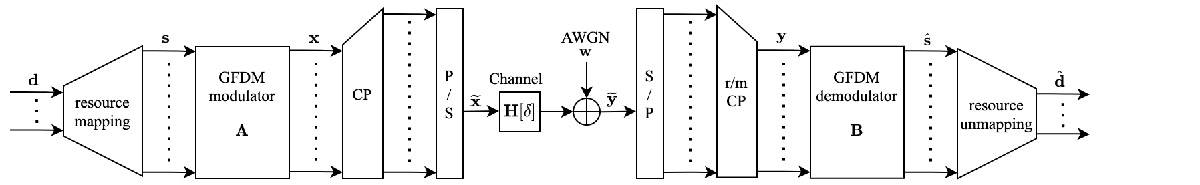

CLEAN_RUN = false;
if CLEAN_RUN
    clear; clc; clf; %#ok<UNRCH>
end

DEBUG = false;  % Plot some figures

addpath(genpath('gfdmlib'));

Simulation parameters.

conste_size = 4;                        % Size of signal constellation (QPSK)
bits_per_sym = log2(conste_size);       % Bits per symbol
Es = 1;                                 % Symbol energy
EbNo = (0:2:20);                        % Eb/N0(dB)
SNR = EbNo + 10*log10(bits_per_sym);    % Convert Eb/N0 to SNR(dB)

N_trial = 1e3;          % Number of Monte Carlo trials

GFDM parameters.

gfdm = struct;

gfdm.K = 256; % Subcarriers
gfdm.M = 16; % Subsymbols

gfdm.K_set = (1:128);      % Used subcarrier index(1 based)
gfdm.M_set = (2:gfdm.M); % Used subsymbol index(1 based)

gfdm.K_on = numel(gfdm.K_set); % Number of used subcarriers
gfdm.M_on = numel(gfdm.M_set); % Number of used used subsymbols

gfdm.pulse = 'dirichlet';     % Pulse shape
gfdm.N_cp = 0;                % CP length

gfdm.D = gfdm.K_on*gfdm.M_on;  % Block size

Prototype filters.

gfdm.g = dirichlet(gfdm.M, gfdm.K);
gfdm.A = g2A(gfdm.g, gfdm.K, gfdm.M);

if DEBUG
    % Plot A matrix
    X = 1:gfdm.M*gfdm.K;    %#ok<UNRCH>
    figure;
    surf(X, X, abs(gfdm.A));
    set (gca, 'ydir', 'reverse');   % Flip Y axis
    title('abs(A)');
    %     figure;
    %     surf(X, X, real(gfdm.A));
    %     set (gca, 'ydir', 'reverse');
    %     title('real(A)');
    %     figure;
    %     surf(X, X, imag(gfdm.A));
    %     set (gca, 'ydir', 'reverse');
    %     title('imag(A)');
end

Monte Carlo simulation.

% BER estimation
ber_est = zeros(size(EbNo));

% Start timer
tic

for n = 1:length(EbNo)
    % Reset error counter
    num_err = 0;
    
    for trial_idx = 1:N_trial
        % ---------- Tx ----------
        % Generate binary data and convert it to symbols
        bin_data = randi([0, 1], bits_per_sym, gfdm.D)';
        dec_data = bi2de(bin_data);
        
        % QPSK mapping
        qpsk_data = pskmod(dec_data, conste_size, pi/conste_size, 'gray');   % QPSK modulation with Gray coding
        % Normalize symbol energy
        % qpsk_data_norm = (Es^0.5) * norm(qpsk_data(1)) * (qpsk_data);
        
        % Debug. Plot QPSK data:
        if DEBUG && (n == 1)
            scatterplot(qpsk_data), grid;
            title('Constellation');
        end
        
        % Resource mapping
        resource_map_data = resource_map(gfdm, qpsk_data);
        % resource_map_data_matrix = reshape(resource_map_data, gfdm.K, gfdm.M);
        
        % GFDM modulation
        gfdm_data = gfdm.A * resource_map_data;
        
        % Cyclic prefix
        cp = gfdm_data(end-gfdm.N_cp+1: end);
        cp_data = [cp; gfdm_data];
        
        % Parallel to serial
        tx_sig = reshape(cp_data, 1, []);
        
        % ------- Channel --------
        %% TODO
        
        % AWGN noise
        rx_sig = awgn(tx_sig, SNR(n));
        
        % ---------- Rx ----------
        %Serial to parallel
        rx_parallel = reshape(rx_sig, [], 1);
        
        % Remove cyclic prefix
        rx_rm_cp_data = rx_parallel(gfdm.N_cp+1: end);
        
        % GFDM demodulation
        rx_demod_data = gfdm.A \ rx_rm_cp_data;
        
         % Resource unmapping
        rx_resource_unmap = resource_unmap(gfdm, rx_demod_data);
        % rx_resource_unmap_matrix = reshape(rx_resource_unmap, gfdm.K, gfdm.M);
        
        % QPSK demodulation
        rx_dec_data = pskdemod(rx_resource_unmap, conste_size, pi/conste_size, 'gray');
        
        % Convert symbols to bits
        rx_bin_data = de2bi(rx_dec_data, bits_per_sym);
        
        % Calculate the number of bit errors
        nErrors = biterr(bin_data, rx_bin_data);
        
        % Increment the error counter
        num_err = num_err + nErrors;
    end
    
    % Estimate BER
    ber_est(n) = num_err/(N_trial * gfdm.D * bits_per_sym);
end

% End timer
toc

Plot PSD.

% TODO

Plot the estimated and theoretical BER data.

% Theoretical BER
berQPSK = berawgn(EbNo', 'psk', conste_size, 'nondiff');

% Plot
figure;
semilogy(EbNo, ber_est, '-*');
hold on;
grid;
semilogy(EbNo, berQPSK);
% legend('GFDM', 'QPSK');
% legend('$\mathcal{|K|}$ = 8', '$\mathcal{|K|}$ = 6', '$\mathcal{|K|}$ = 3', 'Interpreter','latex');
ylabel('BER');
ylim([10^(-6), 10^(-1)]);
xlabel('E_b/N_0 (dB)');

function s = resource_map(p, d)
% Map data vector d onto the (K, M) resource matrix S.
% Returns vec(S).

s_matrix_idx = false(p.K, p.M);
s_matrix_idx(p.K_set, p.M_set) = true;

s = zeros(p.K*p.M, 1);
s(s_matrix_idx) = d;

% s_matrix = reshape(s, p.K, p.M); 
end

function d = resource_unmap(p, s)
% Unmap data vector d from the (K, M) resource matrix S.
% S = reshape(s, K, M).

s_matrix_idx = false(p.K, p.M);
s_matrix_idx(p.K_set, p.M_set) = true;

d = s(s_matrix_idx);
end